clc; clear;

plane = 1;
reg_path = sprintf('C:/Users/RBO/Documents/data/bi_hemisphere/registration/metrics/metrics_plane_%d.fig', plane);
reg_ground_truth_path = sprintf('D:/Jeffs LBM paper data/Fig5/20200910/MH184_both_6mm_FOV_150_600um_depth_410mW_9min_no_stimuli/motion_corr_metrics_plane_30.fig');

Run comparison

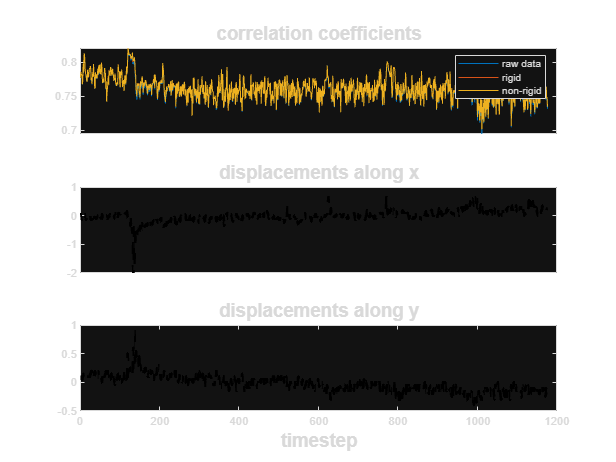

% Open the figures
gt_data = open(reg_ground_truth_path);

v2_data = open(reg_path);

Error using open
File 'C:/Users/RBO/Documents/data/bi_hemisphere/registration/metrics/metrics_plane_1.fig' not found.


% Find all axes objects in the figures
gt_axesObjs = findobj(gt_data, 'Type', 'axes');
v2_axesObjs = findobj(v2_data, 'Type', 'axes');

% Ensure there are at least three axes in both figures
if length(gt_axesObjs) < 3 || length(v2_axesObjs) < 3
    error('One or both figures do not contain at least three axes.');
end

% Loop through the second and third axes
for i = 2:3
    if i == 2
        type_xy = "Y";
    else
        type_xy = "X";
    end

    % Find the line objects in the current axis for both datasets
    gt_lineObjs = findobj(gt_axesObjs(i), 'Type', 'line');
    v2_lineObjs = findobj(v2_axesObjs(i), 'Type', 'line');

    % Extract the X and Y data from the first line object in both datasets
    X_gt = get(gt_lineObjs(1), 'XData');
    Y_gt = get(gt_lineObjs(1), 'YData');
    X_v2 = get(v2_lineObjs(1), 'XData');

    Y_v2 = get(v2_lineObjs(1), 'YData');
    Y_diff = Y_gt(:) - Y_v2(:);
    Y_diff = abs(Y_diff);
    
    % Plot the difference for the current axis
    f = figure;
    plot(X_gt, Y_diff);
    title('Difference in pixel shifts: ground truth vs V2');
    xlabel('timestep');
    ylabel = sprintf('Number of Pixels in %s', type_xy);
    grid on;
    fname = sprintf("%s_%d.png", dataset, i);
    saveas(f, fullfile("../../Documents/data/bi_hemisphere/registration/", fname));
end

differ = Y - y; 


y = combinePlanes(fullfile("../../Documents/data/bi_hemisphere/extracted/MH184_both_6mm_FOV_150_600um_depth_410mW_9min_no_stimuli_00001_00001.h5"), 1);

%%
figure; subplot(1,2,1); set(gca,'xtick',[]); set(gca,'ytick',[]); imagesc(Y(:,:,200)); axis image; colormap 'gray';
subplot(1,2,2); imagesc(y(:,:,200)); axis image; colormap 'gray';
set(gca,'xtick',[]); set(gca,'ytick',[]);

clear('gcf');
imshowpair(Y(:,:,200),y(:,:,200),"diff")

## Extracted Images

h5_fullfile = fullfile("../../Documents/data/bi_hemisphere/extracted_final/MH184_both_6mm_FOV_150_600um_depth_410mW_9min_no_stimuli_00001_00001.h5");
mat_fullfile = matfile("../../Documents/data/ground_truth/MH184_both_6mm_FOV_150_600um_depth_410mW_9min_no_stimuli_00001_plane_30.mat");
new_pipeline_data = h5read(h5_fullfile, '/registration/plane_1/Y');
ground_truth_data = mat_fullfile.Y;

## Comparison

% Check for size equality
if ~isequal(size(new_pipeline_data), size(ground_truth_data))
    error('The arrays have different dimensions and cannot be compared directly.');
end

are_identical = isequal(new_pipeline_data, ground_truth_data);
if are_identical
    disp('The arrays are identical.');
else
    disp('arrays are not identical.');
    
    % abs diff of images
    abs_diff = abs(new_pipeline_data - ground_truth_data);
    max_diff = max(abs_diff(:));
    mean_diff = mean(abs_diff(:));
    disp(['Max difference: ', num2str(max_diff)]);
    disp(['Mean difference: ', num2str(mean_diff)]);
end

arrays are not identical.


Max difference: 2606.7083


Mean difference: 13.385


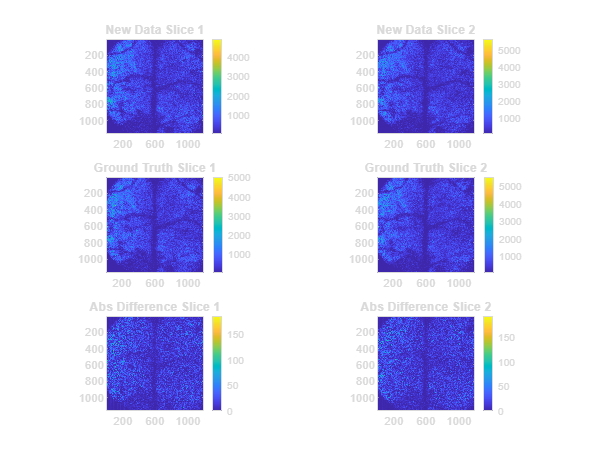

num_frames = 2;
slice_idx = round(linspace(1, num_frames, min(num_frames, 10)));
figure;
for i = 1:length(slice_idx)
    idx = slice_idx(i);
    
    subplot(3, length(slice_idx), i);
    imagesc(new_pipeline_data(:,:,idx));
    title(['New Data Slice ', num2str(idx)]);
    axis equal; axis tight; colorbar;
    
    subplot(3, length(slice_idx), length(slice_idx) + i);
    imagesc(ground_truth_data(:,:,idx));
    title(['Ground Truth Slice ', num2str(idx)]);
    axis equal; axis tight; colorbar;
    
    subplot(3, length(slice_idx), 2*length(slice_idx) + i);
    imagesc(abs(new_pipeline_data(:,:,idx) - ground_truth_data(:,:,idx)));
    title(['Abs Difference Slice ', num2str(idx)]);
    axis equal; axis tight; colorbar;
end